**Cel Ćwiczenia:**

Celem tego ćwiczenia jest zrozumienie dynamicznych zmian zachodzących w zbiorniku cieczy, w którym zachodzi jednocześnie wypływ i grzanie. Dzięki symulacji numerycznej można prześledzić, jak zmieniają się objętość i temperatura cieczy w czasie oraz jakie czynniki wpływają na stabilność układu. Ćwiczenie pozwala na analizę modelu fizycznego w kontekście zjawisk takich jak zachowanie masy i energii, a także umożliwia praktyczne zastosowanie metod numerycznych, w szczególności metody Eulera, w celu rozwiązania równań różniczkowych.

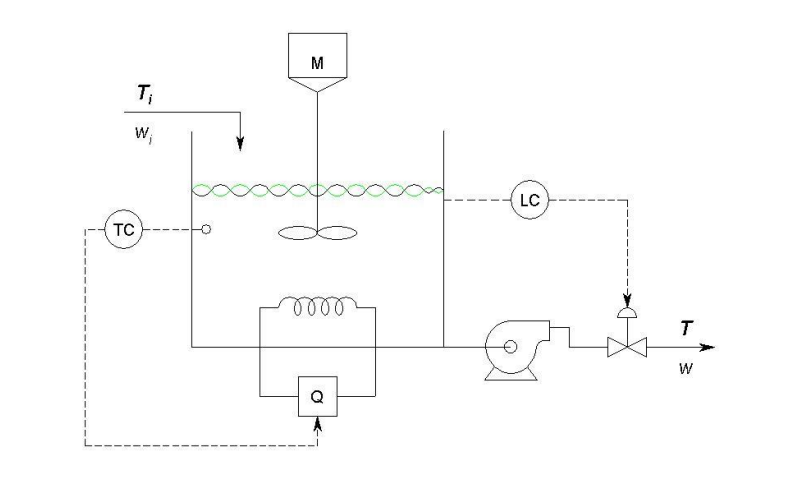

**Wstęp:**

Model zbiornika opiera się na dwóch podstawowych zasadach fizyki. Pierwsza z nich to zasada zachowania masy, która wyrażona jest równaniem różniczkowym **dV/dt�=(wi�−w)/ro** �, gdzie **wi**� i **w** są odpowiednio strumieniami masowymi wlotu i wylotu cieczy, V to objętość cieczy w zbiorniku, a **ro** to jej gęstość. Równanie to mówi, że zmiana objętości cieczy w czasie jest proporcjonalna do różnicy między masami cieczy wpływającej i wypływającej z uwzględnieniem gęstości.

Druga zasada to zachowanie energii, które opisuje równanie dT/dt=(wiC(Ti−T)+Q)/V*ro*C�, gdzie Ti� i T to odpowiednio temperatura strumienia wlotowego i cieczy w zbiorniku, Q to moc grzałki, a C to ciepło właściwe cieczy. Równanie to opisuje zmiany temperatury cieczy w czasie w wyniku wymiany ciepła ze strumieniem wlotowym oraz ciepła dostarczanego przez grzałkę. Uwzględnia ono również wpływ objętości cieczy oraz jej parametrów fizycznych.

Rozwiązywanie tych równań odbywa się metodą Eulera, która opiera się na przybliżeniu pochodnej jako różnicy wartości w kolejnych krokach czasowych. W praktyce oznacza to, że nowa wartość zmiennej stanu jest obliczana jako suma wartości aktualnej i iloczynu przyrostu czasowego oraz tempa zmiany w danym kroku. Metoda ta, mimo swojej prostoty, pozwala na skuteczne modelowanie procesów dynamicznych.

W symulacji uwzględniam ograniczenia, aby zapobiec przelaniu zbiornika (czyli przekroczeniu maksymalnej objętości) lub jego wysuszeniu (spadku objętości poniżej zera). Dzięki temu model jest bardziej realistyczny i lepiej odzwierciedla rzeczywiste warunki pracy zbiornika. Analiza wyników symulacji pozwala na ocenę zachowania układu w różnych warunkach i może być użyteczna w projektowaniu systemów sterowania takich jak regulatory poziomu i temperatury.

**1)** W tym kodzie symuluję zmiany objętości i temperatury cieczy w zbiorniku w czasie. Na początku deklaruję wszystkie potrzebne zmienne, takie jak liczba kroków czasowych, krok symulacji, parametry cieczy (ciepło właściwe, gęstość) oraz wartości początkowe dla temperatury i objętości. Obliczam strumień ciepła Qust, który zależy od różnicy temperatur między cieczą a otoczeniem.

Tworzę wektory temperatury i objętości, które będą zawierały wartości dla każdego kroku czasowego. Początkowa objętość jest ustawiona na wartość Vust. Następnie w pętli for iteracyjnie obliczam zmiany objętości i temperatury. Zmiana objętości wynika z różnicy między przepływami wi i wust, a zmiana temperatury opiera się na bilansie energetycznym. Obliczone zmiany dodaję do aktualnych wartości, uwzględniając krok czasowy `h`.

Tworzę wektor czasu, aby mieć odpowiednią skalę dla osi x na wykresach. Na końcu tworzę dwie wizualizacje: pierwszy wykres pokazuje, jak objętość zmienia się w czasie, a drugi ilustruje zmiany temperatury. Jak widać wykresy nie są zbyt interesujące do dalszej analizy. Objętość jest stała gdyż jej zmiana w czasie nie następuje, natomiast temperatura logarytmicznie, przez ogrzewanie pochodzące od grzejnika. W okolicach 300 K już praktycznie się nie zmienia.

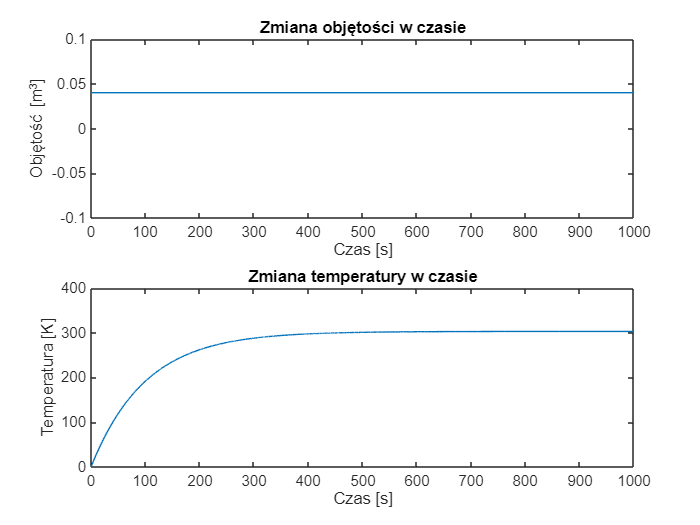

N = 10000;
h = 0.1 ;
Qmax = 25000 ;
wust = 0.4 ;
Ti = 293;
Tust = 303;
Vust = 0.04;
C = 4200;
ro =1000 ;

T = zeros(1,N);
v = zeros(1,N);
wi = wust;
Qust = -(wi* (Ti - Tust) * C);
v(1) = Vust;
for i = 1: N - 1
    dv = (wi - wust)/ ro;
    v(i + 1) = v(i) + dv * h;
    dT = (wi*(Ti - T(i)) + Qust/C) / (v(i) * ro);
    T(i+ 1) = T(i) + dT * h;
end 
t = (0:N-1) * h;
figure;
subplot(2,1,1)
plot(t,v);
title('Zmiana objętości w czasie')
ylabel('Objętość [m^3]')
xlabel ('Czas [s]')
ylim([-0.1, 0.1])
subplot(2,1,2);
plot(t,T);
title('Zmiana temperatury w czasie')
ylabel('Temperatura [K]')
xlabel ('Czas [s]')
axis([0,1000,0,400])

**2)  **W tym miejscu miałem za zadanie zaobserwowanie zmian temperatury w zbiorniku oraz zmian objętości, jeżeli więcej cieczy będzie wypływać niż wpływać. Wykres objętości od czasu charakteryzuje się oczywiście szybkim jej spadkiem do wartości zerowej. Gdyby nie warunek if else wykres dalej charakteryzowałby się spadkiem w stronę coraz to niższych wartości ujemnych, co oczywiście byłoby niemożliwe.W kodzie ustawiłem wartość w strumienia wyjściowego masowego na wartość o 0.1 większą niż w przypadku wejściowego oraz dodałem funkcję if else do pętli for.

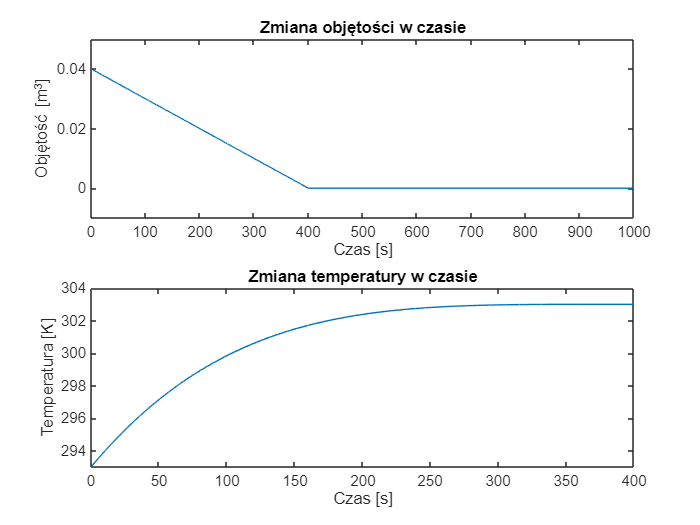

t = (0 : N-1) * h;
v = zeros(1, N);
T = zeros(1, N);
w = wust+0.1;
wi = wust;
v(1) = Vust;
T(1) = Ti;
Q = (-wi * (Ti - Tust)) * C;
for i = 1:N-1
 dV = (wi-w)/ro;
 v(i+1) = v(i) + dV*h;
 if v(i+1) < 0
 v(i+1) = 0;
 end
 dT = (wi * (Ti - T(i)) + Q / C) / (v(i) * ro);
 T(i+1) = T(i) + dT*h;
end
figure;
subplot(2,1,1);
plot(t, v)
title('Zmiana objętości w czasie')
ylabel('Objętość [m^3]')
xlabel ('Czas [s]')
ylim([-0.01, 0.05])
subplot(2,1,2);

plot(t, T)
title('Zmiana temperatury w czasie')
ylabel('Temperatura [K]')
xlabel ('Czas [s]')

**3) ** Na tym etapie winny byłem stworzyć wektor zmian wartości grzania pochodzącego od grzejnika w czasie. Jej funkcję zależną od czasu zaprezentowałem jako pierwszą w subplocie. Objętość bez zmian - podczas tego procesu będzie stała natomiast zmieniać się będzie temperatura w sposób przedstawiony w 3 części subplota. Rośnie ona w sposób charakterystyczny, a jej pojedyncze odcinki świadczą o zmianach ciepła dostarczanego przez grzejnik.

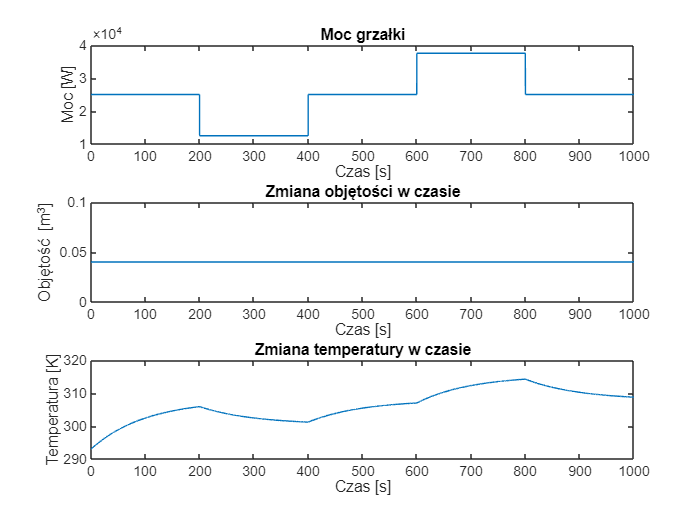

T = zeros(1,N);
v = zeros(1,N);
X = ones(1,floor(N/5));
Qust = 25000;
Q = [Qust*X, 0.5*Qust*X, Qust*X, 1.5*Qust*X, Qust*X];
figure;
subplot(3,1,1);
plot(t,Q)
title("Moc grzałki");
xlabel("Czas [s]");
ylabel("Moc [W]")
wi = wust;
Qust = -(wi* (Ti - Tust) * C);
v(1) = Vust;
for i = 1: N - 1
    dv = (wi - wust)/ ro;
    v(i + 1) = v(i) + dv * h;
    dT = (wi*(Ti - T(i)) + Qust/C) / (v(i) * ro);
    T(i+ 1) = T(i) + dT * h;
end 
t = (0:N-1) * h;
subplot(3,1,2);
plot(t,v);
title('Zmiana objętości w czasie')
ylabel('Objętość [m^3]')
xlabel ('Czas [s]')
axis([0,1000,0,0.1])
T1 = zeros(1,N);
v1 = zeros(1,N);
wi = 0.4;
v1(1) = 0.04;
T1(1) = Ti;

for i = 1:N - 1
    dv = (wi - wust)/ ro;
    v1(i + 1) = v1(i) + dv * h;
    dT = (wi*(Ti - T1(i)) + Q(i)/C) / (v1(i) * ro);
    T1(i+ 1) = T1(i) + dT * h;
end
subplot(3,1,3);
plot(t,T1)
title('Zmiana temperatury w czasie')
ylabel('Temperatura [K]')
xlabel ('Czas [s]')
axis([0,1000,290,320])

**4) **W tym miejscu miałem przeanalizować zachowanie temperatury obiektu w czasie, który jest konkretnej zmiane. Wartości oczywiście miały być stałe dla pojedynczego przebiegu. W tym wypadku zmieniałem wartość strumienia wejściowego masowego. Na wykresach wyraźnie widać, że wraz ze zwiększaniem wartości wi temperatura nieco szybciej się zmienia i przybiera większe wartości w tzw. pikach. Wynika to z charakterystki pompki, która została przeze mnie zamodelowana w ten sposób, że wraz z więszym przypływem cieczy zwiększa się jej temperatura przez większy ruch cząsteczek wody. Zmiany te jednak są mało znaczące i rozchodzi się o kilka kelwinów pomiędzy najmniejszym a największym wi w przebiegach.

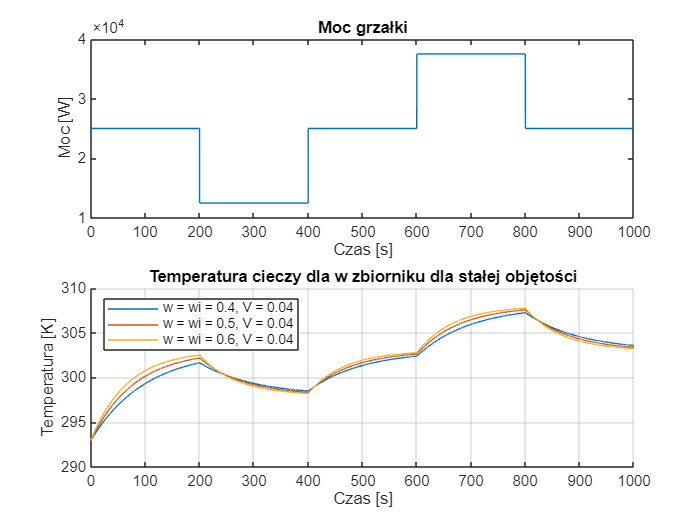

X = ones(1,floor(N/5));
Qust = 25000;
Q = [Qust*X, 0.5*Qust*X, Qust*X, 1.5*Qust*X, Qust*X];
figure;
subplot(2,1,1);
plot(t,Q)
title("Moc grzałki");
xlabel("Czas [s]");
ylabel("Moc [W]")

T1 = zeros(1,N);
v1 = zeros(1,N);
w_nowe = [0.4, 0.5,0.6];
v1(1) = 0.04;
T1(1) = Ti;
subplot(2,1,2);

hold on
for j = 1:length(w_nowe)
    wi = w_nowe(j);
    w = wi;
    Qust = -(wi* (Ti - Tust) * C);
    X = ones(1,floor(N/5));

    Q = [Qust*X, 0.5*Qust*X, Qust*X, 1.5*Qust*X, Qust*X];
    
for i = 1:N - 1
    dv = (wi - w)/ ro;
    v1(i + 1) = v1(i) + dv * h;
    dT = (wi*(Ti - T1(i)) + Q(i)/C) / (v1(i) * ro);
    T1(i+ 1) = T1(i) + dT * h;
end 
plot(t,T1)

end 
axis([0,1000,290,310])
title('Temperatura cieczy dla w zbiorniku dla stałej objętości')
ylabel('Temperatura [K]')
xlabel ('Czas [s]')
grid on
legend('w = wi = 0.4, V = 0.04', 'w = wi = 0.5, V = 0.04', 'w = wi = 0.6, V = 0.04', 'Location','northwest')
hold off

**5) **Zadanie było analogiczne do poprzedniego z tą różnicą, że w tym miejscu każdy z trzech przebiegów ma różne objętości począwszy na 0.4 m^3 a skończywszy na 0.8m^3. Tutaj doznajemy ciekawej obserwacji, ponieważ wyższe objętości zmniejszają wartości temperaturowe wody w naszej pompce. Jest to spowodowane większym "trudem " grzejnika do ogrzania większej ilości cieczy. Im jest jej mniej tym bardziej woda zostanie ogrzana tą samą mocą. Oczywiście programowo jest to opisane w pętli for w ten sposób aby warunek został spełniony.

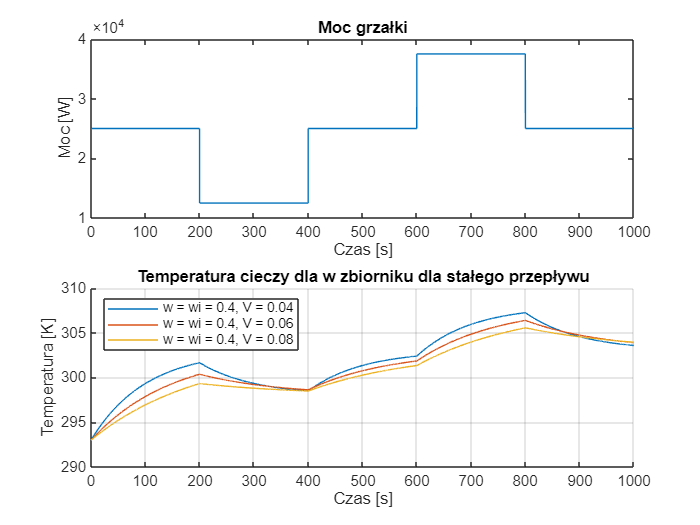

X = ones(1,floor(N/5));

Qust = 25000;
Q = [Qust*X, 0.5*Qust*X, Qust*X, 1.5*Qust*X, Qust*X];
figure;
subplot(2,1,1);
plot(t,Q)
title("Moc grzałki");
xlabel("Czas [s]");
ylabel("Moc [W]")
T1 = zeros(1,N);
v1 = zeros(1,N);
wi = 0.4;

V_ust = [0.04, 0.06, 0.08];
T1(1) = Ti;
subplot(2,1,2);
hold on
for j = 1:length(V_ust)
    v1(1) = V_ust(j);
    w = wi;
    Qust = -(wi* (Ti - Tust) * C);
    X = ones(1,floor(N/5));

    Q = [Qust*X, 0.5*Qust*X, Qust*X, 1.5*Qust*X, Qust*X];
    
    for i = 1:N - 1
        dv = (wi - w)/ ro;
        v1(i + 1) = v1(i) + dv * h;
        dT = (wi*(Ti - T1(i)) + Q(i)/C) / (v1(i) * ro);
        T1(i+ 1) = T1(i) + dT * h;
    end 
    plot(t,T1)

end 
hold off
axis([0,1000,290,310])
title('Temperatura cieczy dla w zbiorniku dla stałego przepływu')
ylabel('Temperatura [K]')
xlabel ('Czas [s]')
grid on
legend('w = wi = 0.4, V = 0.04', 'w = wi = 0.4, V = 0.06', 'w = wi = 0.4, V = 0.08', 'Location','northwest')
hold off

**Podsumowanie**

Podsumowując, symulacja zbiornika ze stałym wypływem i grzaniem pozwala na praktyczne zastosowanie metod numerycznych do analizy zjawisk fizycznych zachodzących w układach dynamicznych. Dzięki wykorzystaniu metody Eulera można precyzyjnie śledzić zmiany objętości i temperatury w czasie, co daje możliwość lepszego zrozumienia wpływu parametrów układu na jego stabilność.